load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module("model_hybrid");
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double';
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

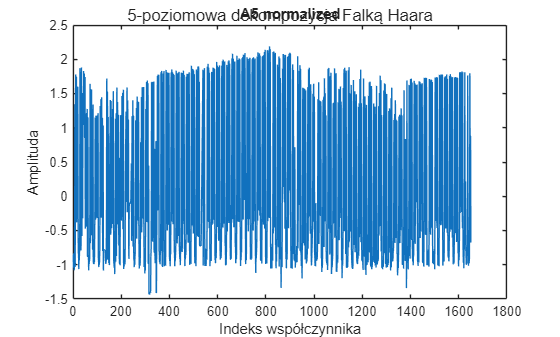

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[D1_norm, center_D1, scale_D1] = normalize(D1);
[A5_norm, center_A5, scale_A5] = normalize(A5);

% 2. RYSOWANIE WYKRESÓW
plot(A5_norm);
title('A5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');
sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
D1_test_norm = (D1_test - center_D1) ./ scale_D1;
A5_test_norm = (A5_test - center_A5) ./ scale_A5;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu

dlugosc_testu_A5 = ceil(dlugosc_testu_oryginalna/32);

% Przewidywania A5 - model hybrydowy
A5_pred_norm = model_hybrid(A5_norm, A5_test_norm(1:dlugosc_testu_A5), 1, 96, 96*7);

Step: 1 / 90
Step: 2 / 90
Step: 3 / 90
Step: 4 / 90
Step: 5 / 90
Step: 6 / 90
Step: 7 / 90
Step: 8 / 90
Step: 9 / 90
Step: 10 / 90
Step: 11 / 90
Step: 12 / 90
Step: 13 / 90
Step: 14 / 90
Step: 15 / 90
Step: 16 / 90
Step: 17 / 90
Step: 18 / 90
Step: 19 / 90
Step: 20 / 90
Step: 21 / 90
Step: 22 / 90
Step: 23 / 90
Step: 24 / 90
Step: 25 / 90
Step: 26 / 90
Step: 27 / 90
Step: 28 / 90
Step: 29 / 90
Step: 30 / 90
Step: 31 / 90
Step: 32 / 90
Step: 33 / 90
Step: 34 / 90
Step: 35 / 90
Step: 36 / 90
Step: 37 / 90
Step: 38 / 90
Step: 39 / 90
Step: 40 / 90
Step: 41 / 90
Step: 42 / 90
Step: 43 / 90
Step: 44 / 90
Step: 45 / 90
Step: 46 / 90
Step: 47 / 90
Step: 48 / 90
Step: 49 / 90
Step: 50 / 90
Step: 51 / 90
Step: 52 / 90
Step: 53 / 90
Step: 54 / 90
Step: 55 / 90
Step: 56 / 90
Step: 57 / 90
Step: 58 / 90
Step: 59 / 90
Step: 60 / 90
Step: 61 / 90
Step: 62 / 90
Step: 63 / 90
Step: 64 / 90
Step: 65 / 90
Step: 66 / 90
Step: 67 / 90
Step: 68 / 90
Step: 69 / 90
Step: 70 / 90
Step: 71 / 90
Step: 72 / 90
S

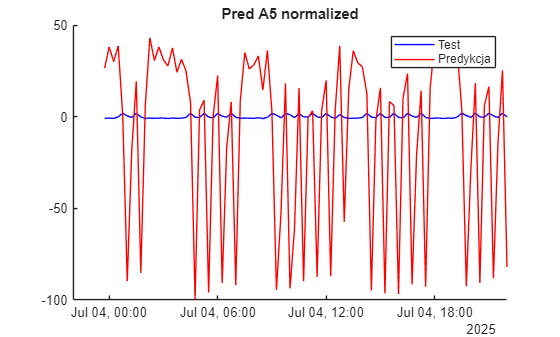


% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_test_norm(1:dlugosc_testu_A5), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A5 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A5_pred = (A5_pred_norm .* scale_A5) + center_A5;

% Obliczamy długości wektorów dla brakujących poziomów (dla zadanego horyzontu)
len_A5 = length(A5_pred);
len_D5 = len_A5;      % Z własności Haara
len_D4 = len_A5 * 2;
len_D3 = len_A5 * 4;
len_D2 = len_A5 * 8;
len_D1 = len_A5 * 16;

% Budowa wektora c_pred
c_pred = [
    A5_pred';              % Predykcja SARIMA
    zeros(len_D5, 1);     % D5 - zerujemy
    zeros(len_D4, 1);     % D4 - zerujemy
    zeros(len_D3, 1);     % D3 - zerujemy
    zeros(len_D2, 1);     % D2 - zerujemy
    zeros(len_D1, 1);     % D1 - zerujemy
];

total_len = length(c_pred);
l_pred = [
    length(A5_pred);
    length(A5_pred);      % D5
    length(A5_pred)*2;    % D4
    length(A5_pred)*4;    % D3
    length(A5_pred)*8;    % D2
    length(A5_pred)*16;   % D1
    length(A5_pred)*32    % Całkowita długość sygnału
];

final_prediction = waverec(c_pred, l_pred, 'haar');      % podejście: A5 Hybryda
y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction')

mae_score = 9.6516

mape_score = mape(y_test, final_prediction')

mape_score = 93.1292

rmse_score = rmse(y_test, final_prediction')

rmse_score = 12.6469

r2_classic = R2_classic(y_test, final_prediction')

r2_classic = -1.3335e+03

r2_alt = R2_alt(y_test, final_prediction')

r2_alt = 1.3328e+03

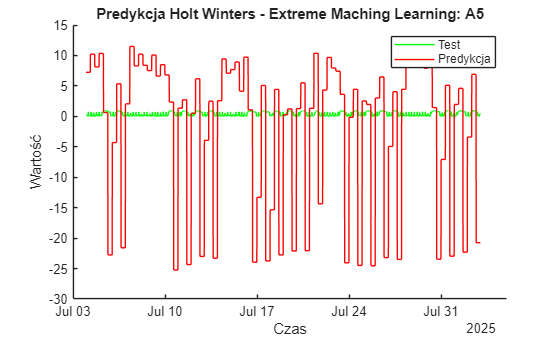


figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ab_diff_test_norm(1:dlugosc_testu_oryginalna), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters - Extreme Maching Learning: A5")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A5_HYBRYDA_month_1.xlsx');